# Tracking:

First, clearly the file locations will be different on your PC than mine, so replace the file in rightVideo with the correct directory.

First, let's see how well the detector output of a3 performs on the entire right hand video:

load 'single_class_ShipDetector.mat'
rightVideo = VideoReader('C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\videos\right_camera_VID.mp4');

frame = readFrame(rightVideo);

while (hasFrame(rightVideo) ~= 0)
     frame = readFrame(rightVideo);
     [bbox,score, label] = detect(ship_DetectorV1,frame);
     img = insertObjectAnnotation(frame,"rectangle",bbox,label);

     imshow(img);
     drawnow
end 


## Tracking using KF

First KF implementation (TERRIBLE). 

load 'single_class_ShipDetector.mat'
videoFile = 'C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\videos\right_camera_VID.mp4';
maxInvisible = 5; %This indicates the maximum number of frames without detection to retain track ID.
nextTrackID = 1;  

tracks = struct( ...
    'KF', {}, ...
    'TrackID', {}, ...
    'Age', {}, ...
    'TotalVisibleCount', {}, ...
    'ConsecutiveInvisibleCount', {});

video = VideoReader(videoFile);
frame = readFrame(video);

while hasFrame(video) %while there are frames in the video:
    frame = readFrame(video); %read the next frame (frame 1 initially)
    
    [bboxes, scores, labels] = detect(ship_DetectorV1, frame); %use the detector on that frame
    
    %Convert bboxes to centroids
    if ~isempty(bboxes)
        
        centroids = [bboxes(:,1)+bboxes(:,3)/2, bboxes(:,2)+bboxes(:,4)/2]; 
    else
        centroids = []; %if no detections (bboxes) leave the centroids as an empty arrayw
    end
    
    %% Predict new locations of existing tracks
    for i = 1:length(tracks)
        tracks(i).KF.predict(); %each track has their OWN kalman filter
    end
    
    %% Assign detections to tracks (nearest neighbor)
    Numtracks = length(tracks);
    Numdetections = size(centroids,1);
    
    cost = zeros(Numtracks, Numdetections);
    for i = 1:Numtracks
        pred = tracks(i).KF.State([1 3]); % x, y
        for j = 1:Numdetections
            cost(i,j) = norm(pred - centroids(j,:));
        end
    end
    
    % Simple greedy assignment
    assignedTracks = zeros(1, Numdetections);
    assignedDetections = zeros(1, Numtracks);
    if ~isempty(cost)
        for j = 1:Numdetections
            [minVal, minIdx] = min(cost(:,j));
            if minVal < 50 % max distance threshold
                if ~assignedTracks(j) && ~assignedDetections(minIdx)
                    assignedTracks(j) = minIdx;
                    assignedDetections(minIdx) = j;
                end
            end
        end
    end
    
    %% Update assigned tracks
    for j = 1:Numdetections
        if assignedTracks(j)
            idx = assignedTracks(j);
            tracks(idx).KF.correct(centroids(j,:)');
            tracks(idx).Age = tracks(idx).Age + 1;
            tracks(idx).TotalVisibleCount = tracks(idx).TotalVisibleCount + 1;
            tracks(idx).ConsecutiveInvisibleCount = 0;
        else
            % Create new track
            %Assume constant velocity
            motionModel = "ConstantVelocity";
            initialLoc = centroids(j,:)';
            %variance in pos and vel
            initialError = [1 25];
            motionNoise = [1 25];
            %assume high meas noise to make the model predict more biasedly on
            %estimated position not bbox
            measurementNoise = 100;
            kf = configureKalmanFilter(motionModel,initialLoc,initialError, motionNoise, measurementNoise); 
            newTrack = struct( ...
                'KF', kf, ...
                'TrackID', nextTrackID, ...
                'Age', 1, ...
                'TotalVisibleCount', 1, ...
                'ConsecutiveInvisibleCount', 0);
            tracks(end+1) = newTrack;
            nextTrackID = nextTrackID + 1;
        end
    end
    
    for i = 1:Numtracks
        if ~assignedDetections(i)
            tracks(i).ConsecutiveInvisibleCount = tracks(i).ConsecutiveInvisibleCount + 1;
        end
    end
    
    tracks([tracks.ConsecutiveInvisibleCount] > maxInvisible) = [];
    
    imshow(frame);
    hold on;
    for i = 1:length(tracks)
        pos = tracks(i).KF.State([1 3]);  % x, y
        pos = pos(:)';                    
        %draw a 40x40 box around predicted centroid, this box is NOT the
        %bbox!!!
        rectangle('Position',[pos-20,40,40],'EdgeColor','yellow','LineWidth',2);
        plot(pos(1), pos(2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
        text(pos(1)+5, pos(2), sprintf('ID %d', tracks(i).TrackID), 'Color', 'cyan');
    end
    hold off;
    drawnow;
end

Second attempt with the KF

load 'single_class_ShipDetector.mat'
videoFile = 'C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\videos\right_camera_VID.mp4';

maxInvisible = 5;       
nextTrackID = 1;     
maxAssignmentDist = 400; %big change here, 400 pixel max assignment distance!

tracks = struct( ...
    'KF', {}, ...
    'TrackID', {}, ...
    'Age', {}, ...
    'TotalVisibleCount', {}, ...
    'ConsecutiveInvisibleCount', {});

video = VideoReader(videoFile);

while hasFrame(video)
    frame = readFrame(video);
    
    [bboxes, scores, labels] = detect(ship_DetectorV1, frame);
    
    if ~isempty(bboxes)
        centroids = [bboxes(:,1)+bboxes(:,3)/2, bboxes(:,2)+bboxes(:,4)/2];
    else
        centroids = [];
    end
    
    for i = 1:length(tracks)
        predict(tracks(i).KF);
    end
    
    Numtracks = length(tracks);
    Numdetections = size(centroids,1);
    
    assignedTracks = zeros(1, Numdetections);
    assignedDetections = zeros(1, Numtracks);
    
    if ~isempty(tracks) && ~isempty(centroids)
        %Compute cost matrix (Euclidean distance)
        cost = zeros(Numtracks, Numdetections);
        for i = 1:Numtracks
            pred = tracks(i).KF.State([1 3]); 
            for j = 1:Numdetections
                cost(i,j) = norm(pred - centroids(j,:));
            end
        end
        
        %Greedy assignment
        for j = 1:Numdetections
            [minVal, minIdx] = min(cost(:,j));
            if minVal < maxAssignmentDist
                if ~assignedTracks(j) && ~assignedDetections(minIdx)
                    assignedTracks(j) = minIdx;
                    assignedDetections(minIdx) = j;
                end
            end
        end
    end
    
    for j = 1:Numdetections
        if assignedTracks(j)
            idx = assignedTracks(j);
            correct(tracks(idx).KF, centroids(j,:)');
            tracks(idx).Age = tracks(idx).Age + 1;
            tracks(idx).TotalVisibleCount = tracks(idx).TotalVisibleCount + 1;
            tracks(idx).ConsecutiveInvisibleCount = 0;
        else
            motionModel = "ConstantVelocity";
            initialLoc = centroids(j,:)';
            initialError = [1 25];
            motionNoise = [1 25];
            measurementNoise = 100; 
            kf = configureKalmanFilter(motionModel, initialLoc, initialError, motionNoise, measurementNoise); 
            
            newTrack = struct( ...
                'KF', kf, ...
                'TrackID', nextTrackID, ...
                'Age', 1, ...
                'TotalVisibleCount', 1, ...
                'ConsecutiveInvisibleCount', 0);
            
            tracks(end+1) = newTrack;
            nextTrackID = nextTrackID + 1;
        end
    end
    
    for i = 1:Numtracks
        if ~assignedDetections(i)
            tracks(i).ConsecutiveInvisibleCount = tracks(i).ConsecutiveInvisibleCount + 1;
        end
    end
    
    tracks([tracks.ConsecutiveInvisibleCount] > maxInvisible) = [];
    imshow(frame);
    hold on;
    for i = 1:length(tracks)
        pos = tracks(i).KF.State([1 3]);  % x, y
        pos = pos(:)';                     
        rectangle('Position',[pos-20,40,40],'EdgeColor','yellow','LineWidth',2);
        plot(pos(1), pos(2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
        text(pos(1)+5, pos(2), sprintf('ID %d', tracks(i).TrackID), 'Color', 'cyan');
    end
    hold off;
    drawnow;
end

Now this also works well, but those quick ID jumps at the beginning throw it off. 

I will now implement a system that only keeps the ID if the track exists for MORE THAN 10 FRAMES. Works as I want it to! 

Next step after this is to utilize AIS data for re-identification.

Now for a nice visual, I'd like to implement velocity arrows:

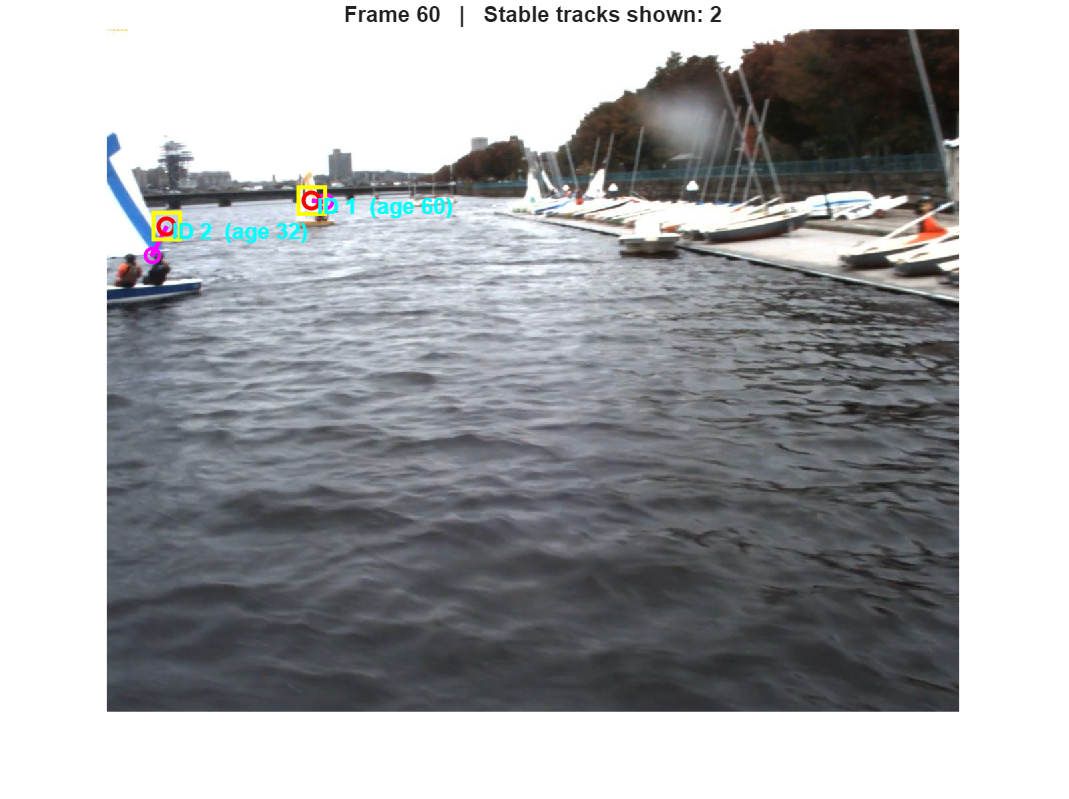

load 'single_class_ShipDetector.mat'
videoFile = 'C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\videos\right_camera_VID.mp4';

%These ID's only exist for confirmed tracks
persistentIDMap = containers.Map('KeyType','double','ValueType','double');
nextPersistentID = 1;

%score based tracking
tracker = trackerGNN( ...
    'TrackLogic',              'Score', ...
    'ConfirmationThreshold',   18, ...   %Tunable
    'DeletionThreshold',       -2, ...
    'AssignmentThreshold',     220, ...
    'FilterInitializationFcn', @initcvkf, ...
    'MaxNumTracks',            200, ...
    'MaxNumDetections',        100);

video = VideoReader(videoFile);
frameCount = 0;

while hasFrame(video)
    frame = readFrame(video);
    frameCount = frameCount + 1;
    currentTime = frameCount;

    [bboxes, ~, ~] = detect(ship_DetectorV1, frame);

    if ~isempty(bboxes)
        centroids = [bboxes(:,1) + bboxes(:,3)/2, bboxes(:,2) + bboxes(:,4)/2];
        numDets = size(centroids,1);
        detections = repmat(objectDetection(0,[0;0]), numDets, 1);

        for j = 1:numDets
            meas = centroids(j,:)';
            detections(j) = objectDetection(currentTime, meas, ...
                'MeasurementNoise', 25*eye(2), ...
                'ObjectClassID', 1);
        end
    else
        detections = [];
    end

    tracks = tracker(detections, currentTime);

    imshow(frame);
    hold on;
    
    showThese = tracks( [tracks.IsConfirmed] & [tracks.Age] >= 10 );
    
    for i = 1:length(showThese)
        t = showThese(i);
    
        origID = t.TrackID;
    
        if ~isKey(persistentIDMap, origID)
            persistentIDMap(origID) = nextPersistentID;
            nextPersistentID = nextPersistentID + 1;
        end
        displayID = persistentIDMap(origID);
    
        state = t.State;
        pos  = state([1 3])';          
    
        vel  = state([2 4])';         
    
        arrow_scale = 12;   %tune this value !!
    
        vel_end = pos + vel * arrow_scale;
    
        %draw velocity arrow
        quiver(pos(1), pos(2), ...      %start
               vel_end(1)-pos(1), ...   %dx
               vel_end(2)-pos(2), ...   %dy
               'Color', 'm', ...        %magenta
               'LineWidth', 2.2, ...
               'MaxHeadSize', 0.4, ...
               'AutoScale', 'off');     
    
        %little circle at the tip of the arrow
        plot(vel_end(1), vel_end(2), 'mo', 'MarkerSize', 7, 'LineWidth', 1.8);
    
        rectangle('Position', [pos-20, 40, 40], ...
            'EdgeColor','yellow','LineWidth',2);
    
        plot(pos(1), pos(2), 'ro','MarkerSize',8,'LineWidth',2);
    
        text(pos(1)+8, pos(2)+8, sprintf('ID %d  (age %d)', displayID, t.Age), ...
            'Color','cyan','FontSize',11,'FontWeight','bold');
    
    end
    
    hold off;
    title(sprintf('Frame %d   |   Stable tracks shown: %d', ...
                  frameCount, length(showThese)));
    drawnow;
end